# Introduction

This demo demonstrates how to read results from ADS datasets (ADS files with extension `.ds`), which are generated either inside ADS Integrated Development Environment (IDE) or using functionality of `TADSInterface` class.

# Current version limitation

**If the ADS project uses external libraries, that project must be open in ADS IDE in order to avoid problems with the libraries.** This is important when running simulation using functionality of `TADSInterface` class. 

In this demo, however, we just read already excisting ADS datasets (generated from ADS IDE), and therefore it is not necessary to open projects.

# Preparation

clc
clear
close all

Create *TADSInterface *object:

ADS = TADSInterface();

Set up environmental variables required for running ADS executables from command line. `SetADSPaths` must be called at least once for each Matlab session.

ADSInstallationDir = 'D:\Program Files\Keysight\ADS2019\';
ADS.SetADSPaths(ADSInstallationDir);

[ADS][14:50:26] All required environmental variables and paths are set and checked.


Make anonymous function to convert S-parameters to dB:

to_dB = @(s) 20*log10(abs(s));

# EXAMPLE 1: Read and plot data from ADS dataset

## ADS Project

We create a simple band-pass microstrip filter project in ADS and run it there. Here is how it looks (see the project `MSFilter_wrk` in the subfolder `ADSProjects` in this demo directory):

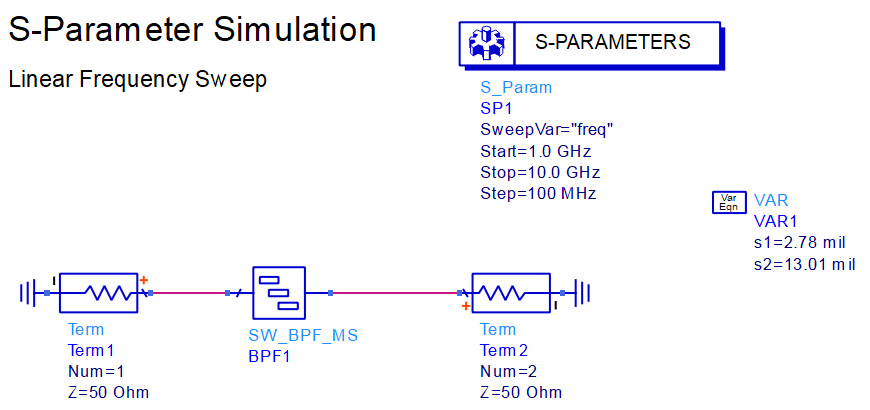

## Read the dataset

The dataset file has name consists of the simulated cell name and the extension *.ds*. 

**IMPORTANT!** 

When the simulation is run from ADS IDE the dataset file is stored in *<Project_wrk>\****data****\<cell_name>.ds *(note the subfolder *data*). However, if the simulation is run from Matlab (or command line), the dataset file is stored in the project directory, i.e. *<Project_wrk>\<cell_name>.ds*. Here we simulated the project manually from ADS IDE, therefore the dataset is located in the sub-folder `data` in the project directory.

DatasetFile = 'D:\Documents\GitHub\MyMatlabCode\基于广义传输矩阵的速度匹配优化方法\Source\ADSInterface\Demos\ADSProjects\MSFilter_wrk\data\MSLine.ds';  % file extension must be ".ds"
ADS.ReadDataset(DatasetFile);

One can click the blue links to open the dataset dump (txt-file) at the line where corresponding variables are defined.

## Optionally: Print names of variables read from the dataset

The variables are divided to "depentent variables" (or "functions") and "independent variables" (or "Arguments").   

Each function depends on one or more arguments.

ADS.PrintDatasetVariables();

## Plot S21 as function of frequency

Get S21 as function of frequency. The fist argument must be a function name, as displayed by `PrintDatasetVariables()` and second argument is a desired argument for the function (in this case we use `'freq'` since we want |`S21|`(f)).

[S21, Freq] = ADS.GetVariableAsFunction('S[2,1]', 'freq');

Plot it using stardard Matlab functions

figure;
plot(Freq, to_dB(S21), '-k', 'LineWidth',2, 'DisplayName','S_{2,1}');
legend show; grid on; xlabel('Frequency'); ylabel('|S_{2,1}|, [dB]');

It is also possible to plot **a function as function of another function** :)

In this case they must have at least one common argument.

In the following example we plot *S21* as function of *S12* (it is a nonsense for a passive structure, it will be just a straight line for a passive device, but it is shown just for illustration), and we can do that because they both depend on "*freq*".

[S21, S12] = ADS.GetVariableAsFunction('S[2,1]', 'S[1,2]');

Plot:

figure;
plot(to_dB(S12), to_dB(S21), '-k', 'LineWidth',2, 'DisplayName','S_{2,1}');
legend show; grid on; xlabel('|S_{1,2}|, [dB]'); ylabel('|S_{2,1}|, [dB]');

# EXAMPLE 2: More complicated dataset: parameter sweep

## ADS project:

The project name is `MSFilter_2ParamSweep_wrk` and it is located in the subfolder `ADSProjects` in this demo directory.

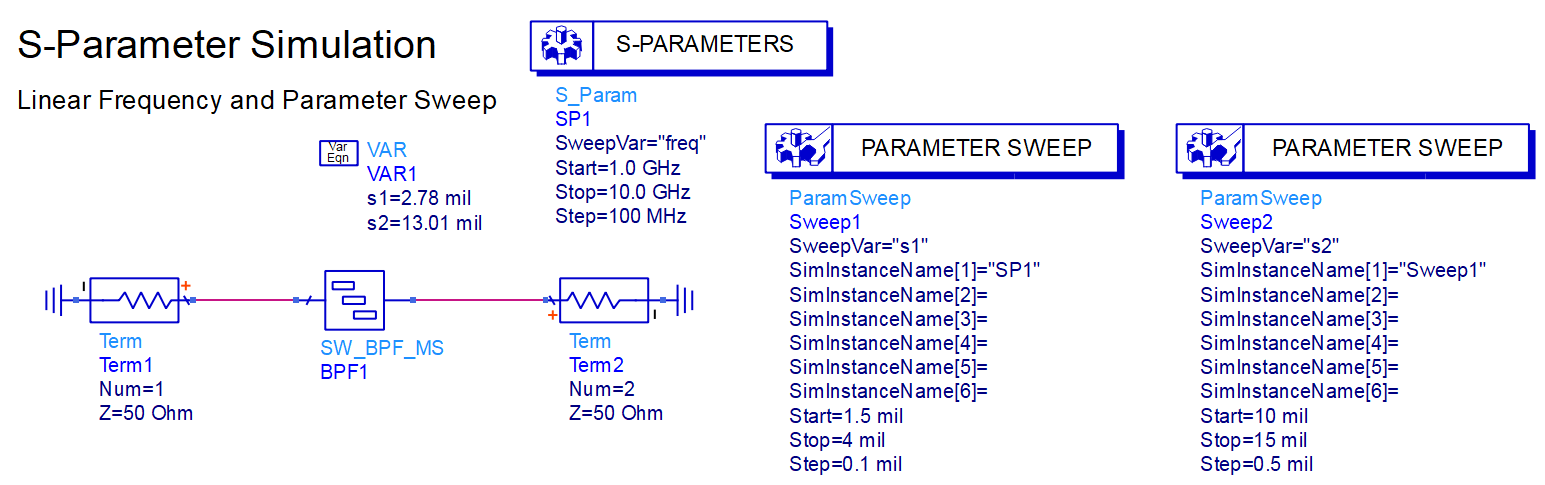

## Read the dataset

It may take a few seconds. Note that the dataset is located in `data` subfolder, which means that this dataset is generated by running simulation manually from ADS IDE.

DatasetFile = 'ADSProjects\MSFilter_2ParamSweep_wrk\data\MSLine.ds';  % file extension must be ".ds"
ADS.ReadDataset(DatasetFile);

## Print names of variables read from the dataset

In this example we have same functions as in Example 1, but now all of them  are functions not only frequency, but also of two swept parameters "s1" and "s2". 

ADS.PrintDatasetVariables();

## Plot S21 as function of frequency

Get S21 as function of frequency.

Since we want just a 1D result (a function of ONLY frequency), we have to fix other arguments which S21 depends on (i.e. "s1" and "s2"). 

[S21, Freq] = ADS.GetVariableAsFunction('S[2,1]', 'freq', 's1',0.06096e-03, 's2',0.36830e-03);

Plot it using stardard Matlab functions

figure;
plot(Freq, to_dB(S21), '-k', 'LineWidth',2, 'DisplayName','S_{2,1}');
legend show; grid on; xlabel('Frequency'); ylabel('|S_{2,1}| @ s1 = 0.06096 mm & s2 = 0.3683 mm, [dB]');


## Plot S21 as function of parameter "s1" at frequency 3 GHz.

Get S21 as function of parameter "`s1`" at frequency 3 GHz.

Since we want just a 1D result (a function of ONLY s1), we have to fix other arguments which S21 depends on (i.e. "`freq`" and "`s2`"). 

[S21, s1] = ADS.GetVariableAsFunction('S[2,1]', 's1', 'freq',3e9, 's2',0.36830e-03);

Plot it using stardard Matlab functions

figure;
plot(s1*1000, to_dB(S21), '-k', 'LineWidth',2, 'DisplayName','S_{2,1}'); % s1*1000 is convertion [m] to [mm] 
legend show; grid on; xlabel('s1, [mm]'); ylabel('|S_{2,1}| @ f = 3 GHz & s2 = 0.3683 mm, [dB]');